# Solving Heat Equation by WCM Based on Daubechies Wavelet

## Daubechies Wavelet

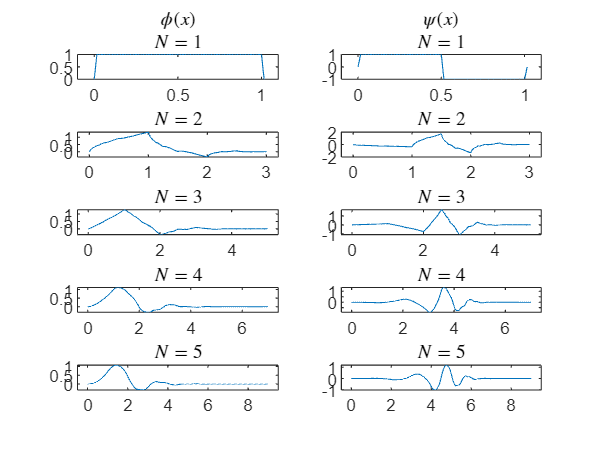

% clear
iter = 6;  % level of accuracy when compute scaling/wavelet coefficients

figure
row = 5; col = 2;
marg = 1/10;

[phi, psi, x] = wavefun("haar", iter);
subplot(row,col,1)
plot(x, phi)
xlim([-marg,1+marg])
title({"$\phi(x)$","$N=1$"},"Interpreter","latex")
subplot(row,col,2)
plot(x, psi)
xlim([-marg,1+marg])
title({"$\psi(x)$","$N=1$"},"Interpreter","latex")

for i = 2:5
    N = i;
    dbM = "db" + num2str(N);
    titlestr = "$N=" + num2str(N) + "$";
    [phi, psi, x] = wavefun(dbM, iter);

    marg = N/10;

    subplot(row,col,2*i-1)
    plot(x,phi)
    xlim([-marg,2*N-1+marg])
    title(titlestr,"Interpreter","latex")
    
    subplot(row,col,2*i)
    plot(x,psi)
    xlim([-marg,2*N-1+marg])
    title(titlestr,"Interpreter","latex")
end

## Periodized Daubechies Wavelet ($p=1$)

Construction

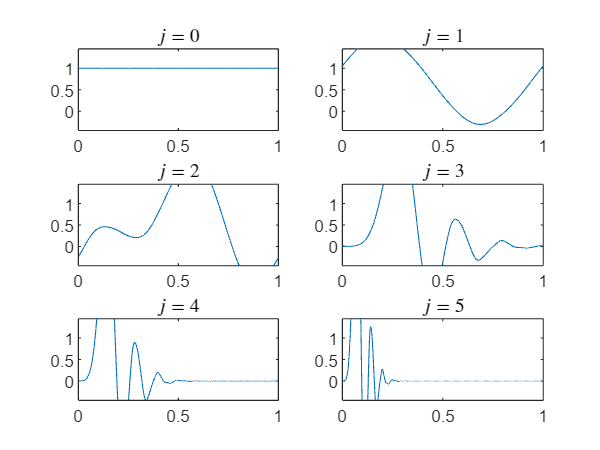

N = 9; D = 2*N;  % the order of Daubechies wavelet
dbM = "db" + num2str(N);
iter = 5;   % level of accuracy when compute scaling/wavelet coefficients
n = 2^iter;

[phi, psi, x] = wavefun(dbM, iter);

figure
for j = 0:5
    [phi_periodized, x_periodized] = periodized(phi, N, iter, j);
    subplot(3,2,j+1)
    plot(x_periodized, phi_periodized)
    ylim([-0.45,1.45])
    titlestr = "$j=" + num2str(j) + "$";
    title(titlestr,"Interpreter","latex")
end

## Example: BVP of 1-dimensional Heat Equation


$$\begin{cases}
u_t =-\alpha \Delta u\quad \text{in } [0,1]\times(0,T]\\
u(x,0) = f(x)\quad \text{in } [0,1]\\
u(0,t) = 0,\quad u(1,t) = 0 \quad \text{in } (0,T]
\end{cases}
\\
f(x) = sin(\pi x)$$


alpha = 1;
a = 0;
b = 1;  % boundary of x
T = 0.5;  % total time
f = @(x) sin(pi*x);

M = 50;     % number of time steps
dt = T/M;
u0 = f(x);
t = linspace(0,T,M+1);

Decomposition example using periodized Daubechies wavelet 

J = 3;  % J Should not greater than log_2(D-1), J = log_2(D-1) is the best
% f = @(x) sin(pi*x) + sin(3*pi*x) + 0.5*randn(size(x));    % example signal
f = @(x) sin(pi*x); % initial function in the PDE we are going to solve

c = zeros(2^J, 1);
phi_periodized = zeros(2^J, n*2^J+1);
[phi_periodized(1,:), x_periodized] = periodized(phi, N, iter, J);
if J > 0
    psi_periodized = cell(1,J);
    x_psi = cell(1, J);
    for j = 1:J
        [psi_periodized{j}, x_psi{j}] = periodized(psi, N, iter, j);
    end
end

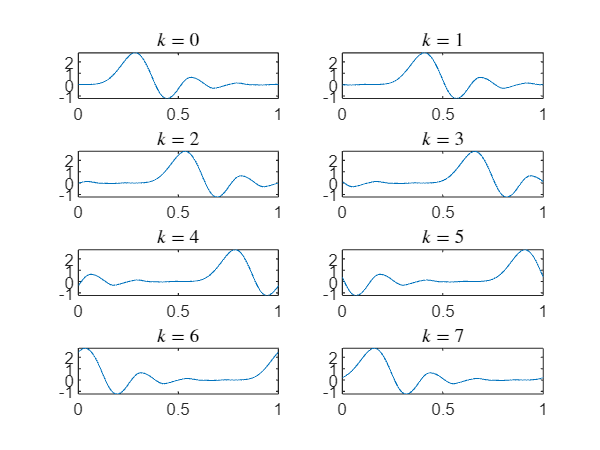

if J > 0
    row = 2^J/2; col = 2;
else
    row = 1; col = 1;
end
for k = 0:2^J-1
    phi_periodized(k+1,1:end-1) = circshift(phi_periodized(1,1:end-1),k*n);
    phi_periodized(k+1,end) = phi_periodized(k+1,1);
    
    subplot(row,col,k+1)
    plot(x_periodized, phi_periodized(k+1,:))
    
    titlestr = "$k=" + num2str(k) + "$";
    title(titlestr,"Interpreter","latex")

    
    c(k+1) = trapz(x_periodized, f(x_periodized).*phi_periodized(k+1,:), 2);
end

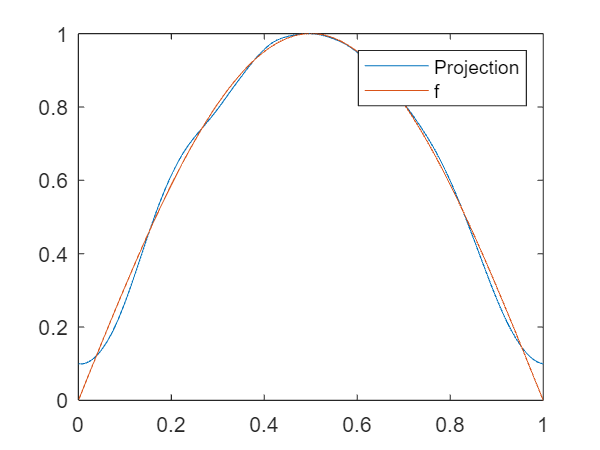


figure
plot(x_periodized, sum(c.*phi_periodized, 1), x_periodized, f(x_periodized))
legend("Projection","f")

## Differentiation Projection Matrix

CDM = @(x,y) (y(3:end) - y(1:end-2)) ./ (x(3:end) - x(1:end-2));
phi_d1 = zeros(size(phi_periodized));
phi_d2 = zeros(size(phi_periodized));
for k = 0:2^J-1
    phi_d1(k+1,:) = [0, CDM(x_periodized,phi_periodized(k+1,:)), 0];
    phi_d2(k+1,:) = [0, CDM(x_periodized,phi_d1(k+1,:)), 0];
end

D0 = form_differentiation_matrix(phi_periodized,n);
D2 = 2^2*form_differentiation_matrix(phi_d2, n);

% D = zeros(2^J,2^J,size(x_periodized));
% for i = 1:length(x_periodized)
%     D(:,:,i) = form_D(phi_d2(:,i),2^J);
% end

J1 = 5;
n = 2^(J1-J);
D0 = form_D(phi_periodized(1,1:n:(size(phi_periodized,2)-1)), 2^J1);

对于此运算，数组的大小不兼容。

出错 form_D (第 6 行)
        rt = rt + diag(ones(order-i+1,1)*phix(i), -(i-1));

相关文档

% D0 = form_differentiation_matrix(phi_periodized,n)';

phi_d2_periodized = periodized([phi_d2 phi_d2(1)], N, iter, J);
D2 = 2^2*form_D(phi_d2_periodized(1:n:(size(phi_d2_periodized,2)-1)), 2^J1);

x = x_periodized(1:n:(size(x_periodized,2)-1));
u = zeros(M,length(x));
c0 = c;
cs = zeros(M,length(x));
C_cal = eye(2^J) - (alpha*dt*D2)/D0;  % combine the coeff and operator

cs(1,:) = c0'*C_cal;
u(1,:) = cs(1,:)*D0;

for i = 2:M
    cs(i,:) = cs(i-1,:)*C_cal;
    u(i,:) = cs(i,:)*D0;
end
x = [x, b];
u = [u, u(:,1)];
u = [f(x); u];

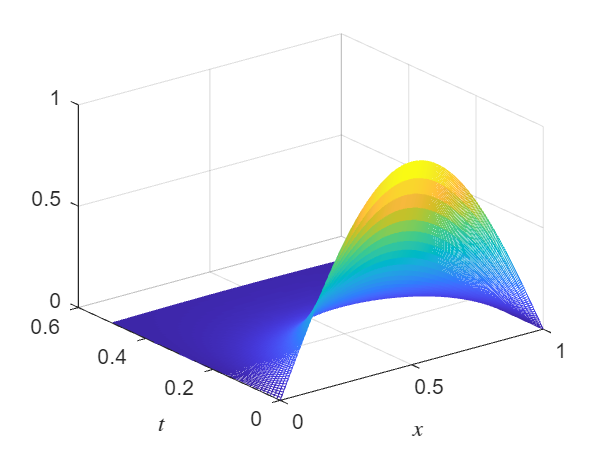

u_explicit_fun = @(x,t) sin(pi*x).*exp(-alpha*pi^2*t);

figure
[mesh1,mesh2] = meshgrid(x_periodized,t);
u_explicit = u_explicit_fun(mesh1,mesh2);
mesh(mesh1,mesh2,u_explicit);
xlabel("$x$","Interpreter","latex")
ylabel("$t$","Interpreter","latex")

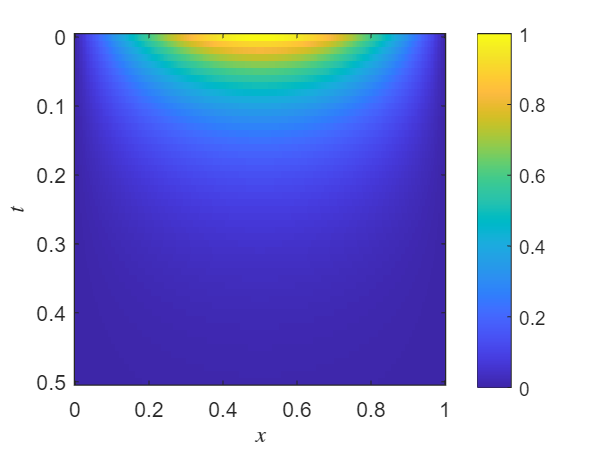


figure
imagesc(x_periodized,t,u_explicit)
colorbar
xlabel("$x$","Interpreter","latex")
ylabel("$t$","Interpreter","latex")

% u(u>1) = 1; u(u<-1) = -1;
figure
imagesc(x,t,u)
colorbar
xlabel("$x$","Interpreter","latex")
ylabel("$t$","Interpreter","latex")

f_d1 = @(x) pi*cos(pi*x);
f_d2 = @(x) -pi*2*sin(pi*x);

[hk,gk] = wfilters(dbM,"r");
phi_ = sum([hk,zeros(1,8)]'.*phi_periodized,1);

对于此运算，数组的大小不兼容。

相关文档

[phi__,x__] = periodized(phi,N,iter,3);

figure
hold on
plot(x_periodized,phi_,x__,phi__)

hk_aug = [hk, zeros(1,length(hk))];
A = zeros(D-1);
for i = 1:N
    A(i,1:2*i-1) = fliplr(hk_aug(1:2*i-1));
end
for i = N+1:D-1
    A(i,1:end) = fliplr(hk_aug(2*i+1-D:2*i-1));
end
A = sqrt(2)*A;

B = zeros(D-1);
for i = 1:N-1
    B(i,1:2*i) = fliplr(hk_aug(1:2*i));
end
for i = N:D-1
    B(i,1:end) = fliplr(hk_aug(2*i+2-D:2*i));
end
B = sqrt(2)*B;

[V,eigvalues] = eig(A);

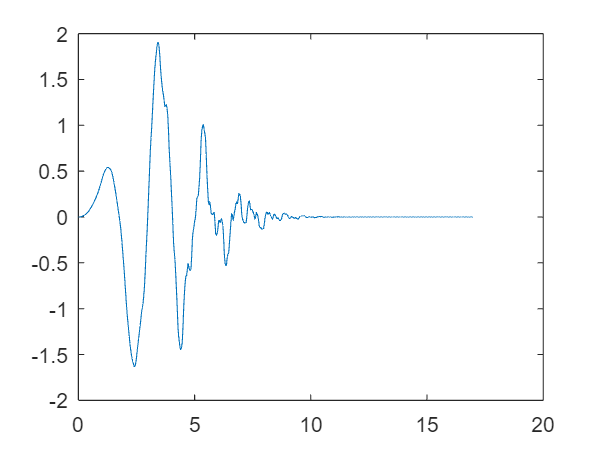

J = 8;
d = 2;
A_derivative = 2^d*A;
B_derivative = 2^d*B;

Ms = zeros(1, 2^J);
for i = 1:2^J
    M;
end

V = V/sum(V(:,1));
% V = V*factorial(d)/sum(V(:,3).*Ms);     % ???
phi_d2 = V(:,3);   % the first eigvalue is 1, the third is 1/2, the fourth is 1/4, ...
if iter > 0
    phi_d2s = cell(1,iter);
    phi_d2s{1} = B_derivative*phi_d2;
    for j = 2:iter
        phi_d2s{j} = zeros(D-1,2^(j-1));
        for i = 1:2^(j-2)
            phi_d2s{j}(:,i) = A_derivative*phi_d2s{j-1}(:,i);
            phi_d2s{j}(:,i+2^(j-2)) = B_derivative*phi_d2s{j-1}(:,i);
        end
    end
    
    % combine
    phi_combined = zeros(2^iter*(D-1),1);
    phi_combined(1:2^iter:end) = phi_d2;
    for j = 1:iter
        temp = phi_d2s{j}';
        phi_combined((2^(iter-j)+1):2^(iter-j+1):end) = temp(:);
    end
    phi_d2 = phi_combined;
end
phi_d2 = phi_d2';

figure
xx = linspace(0,D-1,2^iter*(D-1)+1);
xx = xx(1:end-1);
plot(xx,phi_d2)